clc, clear all

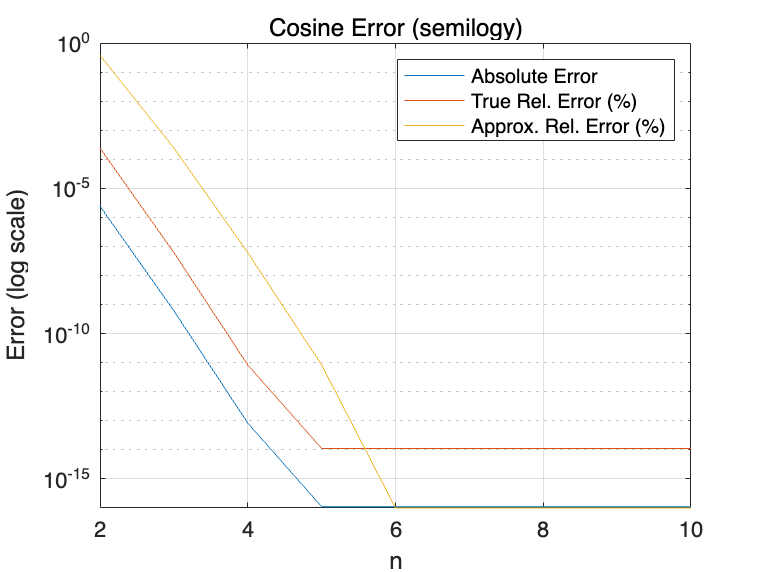

% problem1
x = deg2rad(5);
exact_sin = sin(x) ;
exact_cos = cos(x) ;

function fac = factorial(n) 
    fac = 1;
    for i = 1:n
    fac  = fac * i ;
    end 

end

function approx_sin = approx_sin(n,x)
    approx_sin = 0 ;
    for i = 0:n-1
        approx_sin = approx_sin + x^(2*i+1)/factorial(2*i+1)*(-1)^i;
    end
end

function approx_cos = approx_cos(n,x)
    approx_cos = 0 ;
    for i = 0:n-1
        approx_cos = approx_cos + x^(2*i)/factorial(2*i)*(-1)^i;
    end
end

% 절대오차
abs_error_sin = [];
abs_error_cos = [];
t_error_sin = [];
t_error_cos = [];
a_error_sin = [];
a_error_cos = [];

for i = 2:10 
    abs_error_sin_cal = abs(exact_sin - approx_sin(i,x));
    abs_error_cos_cal = abs(exact_cos - approx_cos(i,x));
    t_error_sin_cal = abs(exact_sin - approx_sin(i,x))/abs(exact_sin);
    t_error_cos_cal = abs(exact_cos - approx_cos(i,x))/abs(exact_cos);
    a_error_sin_cal = abs(approx_sin(i,x)-approx_sin(i-1,x))/abs(approx_sin(i-1,x));
    a_error_cos_cal = abs(approx_cos(i,x)-approx_cos(i-1,x))/abs(approx_cos(i-1,x));
    abs_error_sin(end+1) = max(abs_error_sin_cal, 1e-16);
    abs_error_cos(end+1) = max(abs_error_cos_cal, 1e-16);
    t_error_sin(end+1) = max(t_error_sin_cal*100, 1e-16);
    t_error_cos(end+1) = max(t_error_cos_cal*100, 1e-16);
    a_error_sin(end+1) = max(a_error_sin_cal*100, 1e-16);
    a_error_cos(end+1) = max(a_error_cos_cal*100, 1e-16);

end

figure;
semilogy(2:10, abs_error_cos);
hold on ;
semilogy(2:10, t_error_cos);
semilogy(2:10, a_error_cos);
legend('Absolute Error', 'True Rel. Error (%)', 'Approx. Rel. Error (%)');
xlabel('n');
ylabel('Error (log scale)');
title('Cosine Error (semilogy)');
grid on;
hold off ;

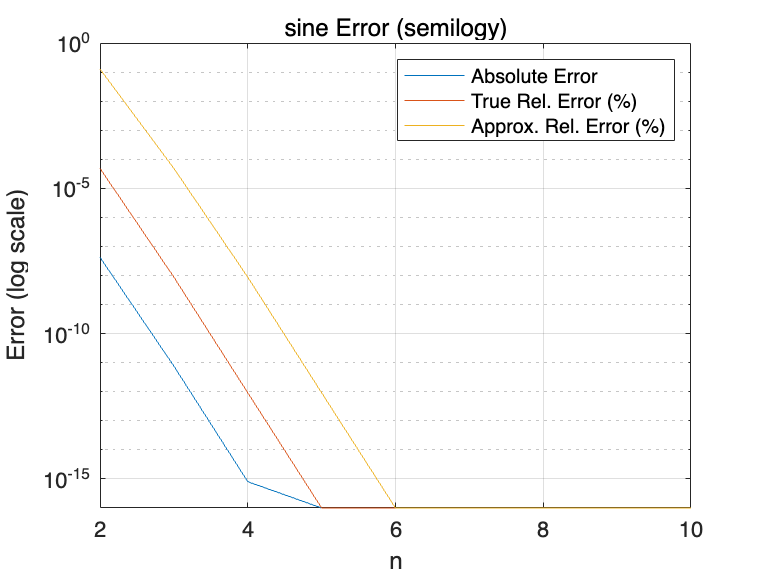



figure;
semilogy(2:10 ,abs_error_sin);
hold on ;
semilogy(2:10, t_error_sin);
semilogy(2:10, a_error_sin);
legend('Absolute Error', 'True Rel. Error (%)', 'Approx. Rel. Error (%)');
xlabel('n');
ylabel('Error (log scale)');
title('sine Error (semilogy)');
grid on;
hold off ;

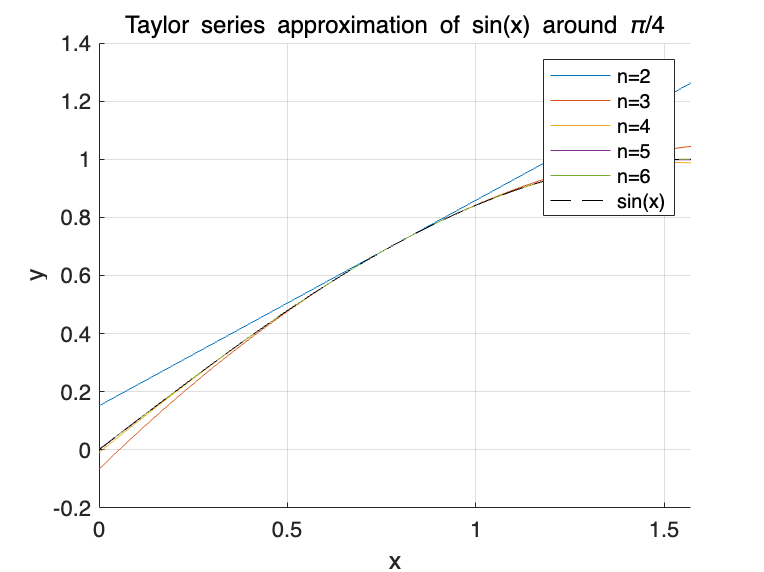

% problem3
interval_x = linspace(0,pi/2, 101) ;
x_cal = pi/3;
exact_sin = sin(x_cal);
n = 2:6;
truncation_error = [];

function taylor_sin = taylor_sin(n,x,a) 
    taylor_sin = 0;
    sign_sin = 1;
    sign_cos = 1;
    for i = 1:n;
        if mod(i,2) == 1
            taylor_sin = taylor_sin + sign_sin*sin(a)*((x-a)^(i-1))/factorial(i-1);
            sign_sin = -1*sign_sin;
        else 
            taylor_sin = taylor_sin + sign_cos*cos(a)*((x-a)^(i-1))/factorial(i-1);
            sign_cos = -1*sign_cos;
        end
    end
end 

figure;
hold on;
for i = n
    approx_vec = zeros(size(interval_x)); 
    for j = 1:length(interval_x)
        approx_vec(j) = taylor_sin(i, interval_x(j), pi/4);
    end
    plot(interval_x, approx_vec, 'DisplayName', ['n=' num2str(i)]);
    
end
plot(interval_x, sin(interval_x), 'k--', 'DisplayName', 'sin(x)');
legend;
xlabel('x'); ylabel('y');
title('Taylor series approximation of sin(x) around \pi/4');
grid on;
hold off;

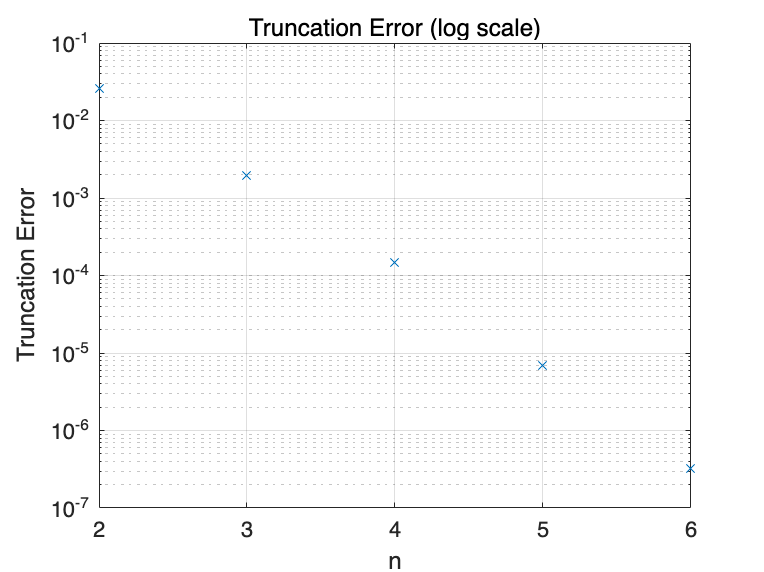


figure;
truncation_error = [];
for i = n 
    err = abs(exact_sin - taylor_sin(i, x_cal, pi/4));
    truncation_error(end+1) = max(err, 1e-16);  % python에서는 그냥 처리가 되는데 매트랩은 처리를 해줘야함.
end

figure;
semilogy(n, truncation_error, 'x', 'LineStyle', 'none');
xlabel('n');
ylabel('Truncation Error');
title('Truncation Error (log scale)');
grid on;